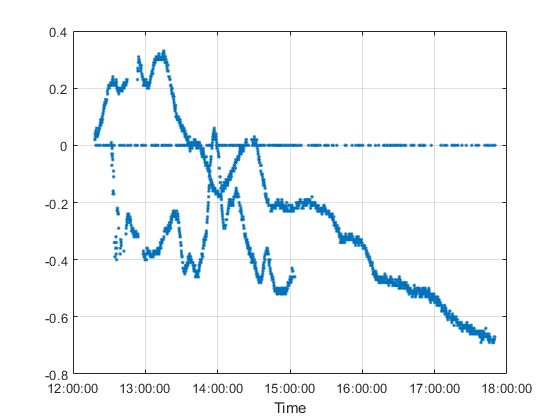

clear all
% 假設檔案在同一個資料夾內
fileList = dir('*.txt'); % 選取當前資料夾下的所有 txt 檔案
data = []; % 用來儲存所有檔案的數據
time = []; % 用來儲存時間的數據
n=length(fileList);

for j = 1:n
    % 讀取每個檔案
    filename = fileList(j).name;
    fileID = fopen(filename, 'r');
    
    % 讀取檔案內容，並忽略空行
    fileData = textscan(fileID, '%s %f %f %f %f %f %f %f %f %f %f', 'Delimiter', '\t');
    
    % 關閉檔案
    fclose(fileID);
    
    % 把該檔案的數據加入到總陣列
    time = [time; fileData{1}]; % 第一列是時間的字串
    data = [data; fileData{2:end}]; % 跳過第一欄時間戳，加入其他數據
end
time = datetime(time, 'InputFormat', 'HH:mm:ss.SS'); % 假設時間格式為 HH:MM:SS.SS
time = time(~isnat(time));

acc=data(:,1:3);
lat=data(:,4);
lon=data(:,5);
alt=data(:,6);
gps=data(:,7);
tem=data(:,8);
v=data(:,9);
i=data(:,10);

figure;
plot(time, i, '.');
xlabel('Time');
grid on;
datetick('x', 'HH:MM:SS'); % 格式化 x 軸為時間格式